# Converting a RasCAL1Project to RAT format. 

If you have a number of old rascal projects that you would like to load into RAT, it's not necessary to re-make the project from scratch. Rather, you can simply run the converstion utility supplied with the RAT repo to translate the project directly.

The project we are going to use for demonstrations comes from the RasCAL_2019 distro, and is an alaysis of a monolayer of DSPC analysed at multiple contrasts. We use various deuterations of DSPC, so either tail-deuterated, head deuterated, fully deuterated or hydrogenated....

                                                                                        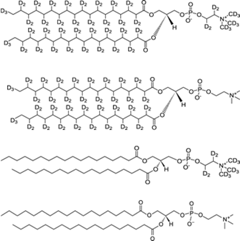

..and these are measured either on D2O or ACMW, to give 7 contrasts in all.

The original R1 project is in 'monolayerVolumeModel.mat'. The custom model is 'Model_IIb.m'. To do the conversion, we simply run the utility....

problem = r1ToProjectClass('monolayerVolumeModel.mat')

problem =          modelType: 'custom layers'
    experimentName: 'monolayerVolumeModel'
          geometry: 'air/substrate'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name             Min         Value          Max    Fit? 
    _    _____________________    ___    ________________    ___    _____

    1    "Substrate Roughness"     1     2.99796427819489      8    true 
    2    "Area per molecule"      47     53.0526804576648    100    true 
    3    "Head Thickness"          7     12.2763338367799     20    true 
    4    "Theta"                   0     28.8705410498363     50    true 


    Bulk In: ------------------------------------------------------------------------------------------------

problem.setCustomFile(1,'path', 'examples/miscellaneous/convertRasCAL1Project');

...and that's it! We have a full RAT projectClass with all the relevant parameters in the correct place.

To run this, we make a controls.block as ususal, send it to RAT and see what we end up with...

controls = controlsClass();
[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________

Elapsed time is 0.011081 seconds.

Finished RAT ______________________________________________________________________________________________ 



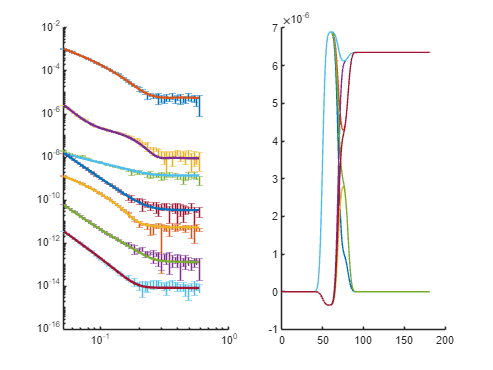


% Plot this out
figure; clf; hold on
plotRefSLD(problem,results);

Looking at the project, we see a couple of things that we might like to change...

- The bulk out parameters are not being fit, we would like to fit these, so change the fit values of these to 'true'..

- The same goes for the scalefactor

- We would like to do a Bayesian analysis, so set the priors to be visible..

- Set some priors on the 'bulk out' parameters

We do this by modifying our projectClass with the class methods as usual....

problem.setBulkOut(1,'fit',true);

problem.setBulkOut(2,'fit',true);
problem.setScalefactor(1,'fit',true);

problem.showPriors = true;
problem.bulkOut.setPrior(1,'gaussian',6.35e-6,1e-8);
problem.bulkOut.setPrior(2,'gaussian',0,1e-7);
disp(problem)

         modelType: 'custom layers'
    experimentName: 'monolayerVolumeModel'
          geometry: 'air/substrate'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name             Min         Value          Max    Fit?     Prior Type    mu    sigma
    _    _____________________    ___    ________________    ___    _____    __________    __    _____

    1    "Substrate Roughness"     1     2.99796427819489      8    true     "uniform"     0      Inf 
    2    "Area per molecule"      47     53.0526804576648    100    true     "uniform"     0      Inf 
    3    "Head Thickness"          7     12.2763338

## Running a full analysis..

We will, as usual, run a Bayesian analysis using DREAM.

Set our controls block to parallelise over contrasts, and select the Bayes sampler....

controls.parallel = 'contrasts';
controls.procedure = 'dream'

controls =   controlsClass with properties:

            parallel: 'contrasts'
           procedure: 'dream'
    calcSldDuringFit: 0
             display: 'iter'
      resampleParams: [0.900000000000000 50]
            nSamples: 50000
             nChains: 10
     jumpProbability: 0.500000000000000
          pUnitGamma: 0.200000000000000
       boundHandling: 'fold'
            adaptPCR: 0


..and run the fit (using the defaults).

[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running DREAM

------------------ Summary of the main settings used ------------------


DREAMPar = struct with fields:
            nParams: 9
            nChains: 10
       nGenerations: 5000
           parallel: 0
                CPU: 1
    jumpProbability: 0.500000000000000
         pUnitGamma: 0.200000000000000
                nCR: 3
              delta: 3
              steps: 100
               zeta: 1.000000000000000e-12
            outlier: 'iqr'
           adaptPCR: 0
           thinning: 1
                ABC: 0
            epsilon: 0.025000000000000
                 IO: 0
        storeOutput: 0
                  R: [10×10 double]


-----------------------------------------------------------------------

 DREAM:    0.0% [........................................]


 DREAM:  100.0% [****************************************]
Elapsed time is 11.466546 seconds.

Finished RAT ______________________________________________________________________________________________ 



Plot everything out and we're done.....

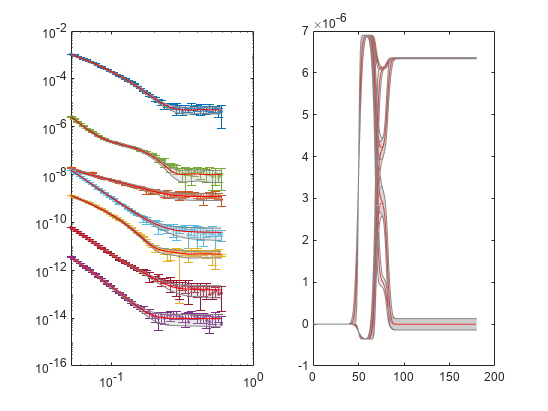

figure(30); clf;
bayesShadedPlot(problem, results,'KeepAxes',true,'interval',95,'q4',false);

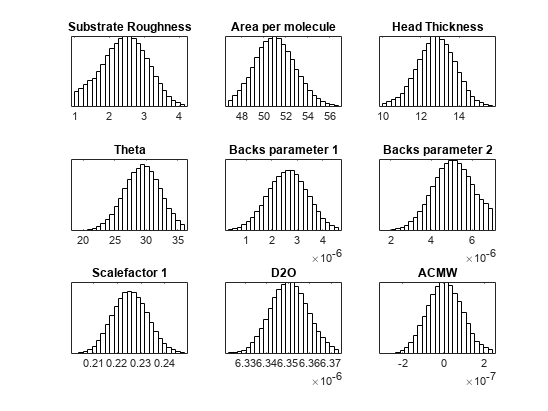

h3 = figure(40); clf
plotHists(results,h3,'smooth',true);

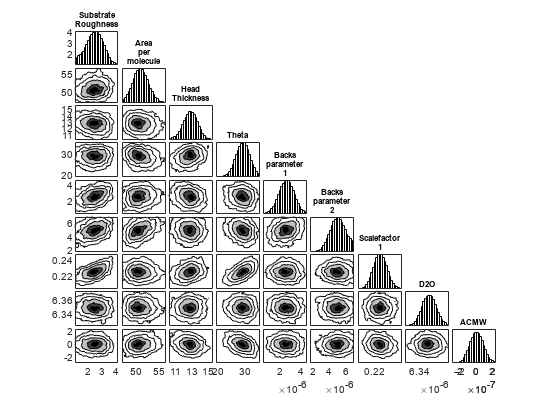

h4 = figure(5); clf
cornerPlot(results,h4,'smooth',false)